clear; clc;
cvx_clear;

addpath './../classes'

% BB84 states

s0  = [1;0]

s0 =      1
     0


s1  = [0;1]

s1 =      0
     1


sp  = [1;1]/sqrt(2)

sp =     0.7071
    0.7071


sm  = [1;-1]/sqrt(2)

sm =     0.7071
   -0.7071


spi  = [1;i]/sqrt(2)

spi =    0.7071 + 0.0000i
   0.0000 + 0.7071i


smi  = [1;-i]/sqrt(2)

smi =    0.7071 + 0.0000i
   0.0000 - 0.7071i



states = [s0, s1, sp, sm, spi, smi  ]

states =    1.0000 + 0.0000i   0.0000 + 0.0000i   0.7071 + 0.0000i   0.7071 + 0.0000i   0.7071 + 0.0000i   0.7071 + 0.0000i
   0.0000 + 0.0000i   1.0000 + 0.0000i   0.7071 + 0.0000i  -0.7071 + 0.0000i   0.0000 + 0.7071i   0.0000 - 0.7071i


% Pauli matrices

E = [1 0; 0 1];
X = [0 1; 1 0];
Y = [0 -i; i 0];
Z = [1 0; 0 -1];

% 1. Definition der Achsenbereiche
lambda_vec = linspace(0, 1, 100); 
mu_vec = linspace(0, 0.75, 100);

% 2. Matrix für die Ergebnisse voralokieren (wichtig für die Performance!)
Bob = zeros(length(lambda_vec), length(mu_vec));
Entanglement = zeros(length(lambda_vec), length(mu_vec));

% 3. Geschachtelte for-Schleife
for i = 1:length(mu_vec)         % Schleife über die Zeilen (y-Werte)
    fprintf(" i =  %d \n", i);

    mu = mu_vec(i);
    K0 = sqrt(1-mu)*E;
    K1 = sqrt(mu/3)*X;
    K2 = sqrt(mu/3)*Y;
    K3 = sqrt(mu/3)*Z;
        
    N0 = kron( K0, E);
    N1 = kron( K1, E);
    N2 = kron( K2, E);
    N3 = kron( K3, E);

    for j = 1:length(lambda_vec)    
        
        lambda = lambda_vec(j);

        cloner = SDP_1to2_AsymmetricCloning(states, lambda);
        [primal_optimum, J] = cloner.solvePrimal();
        kraus_ops = Utils.getKrausOperators(J,1,2);
        
        rho_in = s0*s0';
        rho_out =Utils.applyChannel(kraus_ops,rho_in);
        
        rho_final = N0*rho_out*N0' + N1*rho_out*N1' + N2*rho_out*N2' + N3*rho_out*N3';
        
        rho_Bob = PartialTrace( rho_final,[2],[2,2]);
        fidelity_Bob = real( trace(rho_in*rho_Bob ) );
        Bob(i, j) = fidelity_Bob;

        con = Concurrence(rho_final);
        Entanglement(i, j) = con;
    end
end

 i =  1 
 i =  2 
 i =  3 
 i =  4 
 i =  5 
 i =  6 
 i =  7 
 i =  8 
 i =  9 
 i =  10 
 i =  11 
 i =  12 
 i =  13 
 i =  14 
 i =  15 
 i =  16 
 i =  17 
 i =  18 
 i =  19 
 i =  20 
 i =  21 
 i =  22 
 i =  23 
 i =  24 
 i =  25 
 i =  26 
 i =  27 
 i =  28 
 i =  29 
 i =  30 
 i =  31 
 i =  32 
 i =  33 
 i =  34 
 i =  35 
 i =  36 
 i =  37 
 i =  38 
 i =  39 
 i =  40 
 i =  41 
 i =  42 
 i =  43 
 i =  44 
 i =  45 
 i =  46 
 i =  47 
 i =  48 
 i =  49 
 i =  50 
 i =  51 
 i =  52 
 i =  53 
 i =  54 
 i =  55 
 i =  56 
 i =  57 
 i =  58 
 i =  59 
 i =  60 
 i =  61 
 i =  62 
 i =  63 
 i =  64 
 i =  65 
 i =  66 
 i =  67 
 i =  68 
 i =  69 
 i =  70 
 i =  71 
 i =  72 
 i =  73 
 i =  74 
 i =  75 
 i =  76 
 i =  77 
 i =  78 
 i =  79 
 i =  80 
 i =  81 
 i =  82 
 i =  83 
 i =  84 
 i =  85 
 i =  86 
 i =  87 
 i =  88 
 i =  89 
 i =  90 
 i =  91 
 i =  92 
 i =  93 
 i =  94 
 i =  95 
 i =  96 
 i =  97 
 i =  98 
 i =  99 
 i =  100 


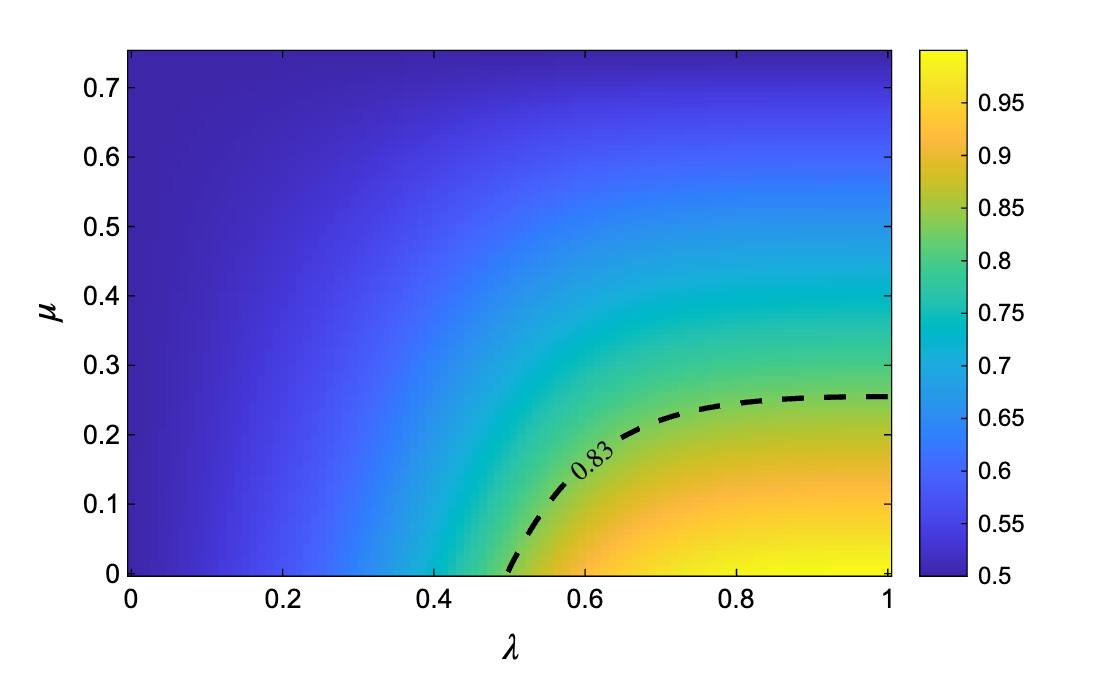

% Visualisierung as Heatmap
figure('Color', 'w');
imagesc(lambda_vec, mu_vec, Bob); % Erstellt die Heatmap
set(gca, 'YDir', 'normal','FontName', 'Arial'); 

hold on; 


target_z = 0.83;
[C, h] = contour(lambda_vec, mu_vec, Bob, [target_z, target_z], ...
                 'LineColor', 'k', ...      
                 'LineWidth', 2, ...        
                 'LineStyle', '--');        

clabel(C, h, 'FontSize', 10, 'Color', 'k', 'Interpreter', 'latex');

hold off;

colorbar; 
colormap('parula'); 

set(gca, 'XColor', 'k', 'YColor', 'k');


xlabel('$\lambda$', 'Interpreter', 'latex', 'Color', 'k', 'FontSize', 14);
ylabel('$\mu$', 'Interpreter', 'latex', 'Color', 'k', 'FontSize', 14);

cb = colorbar;
cb.Color = 'k'; 

% --- EXPORT ---
exportgraphics(gcf, './figures/BB84Attack_Fidelity_6States.jpg', 'Resolution', 300);

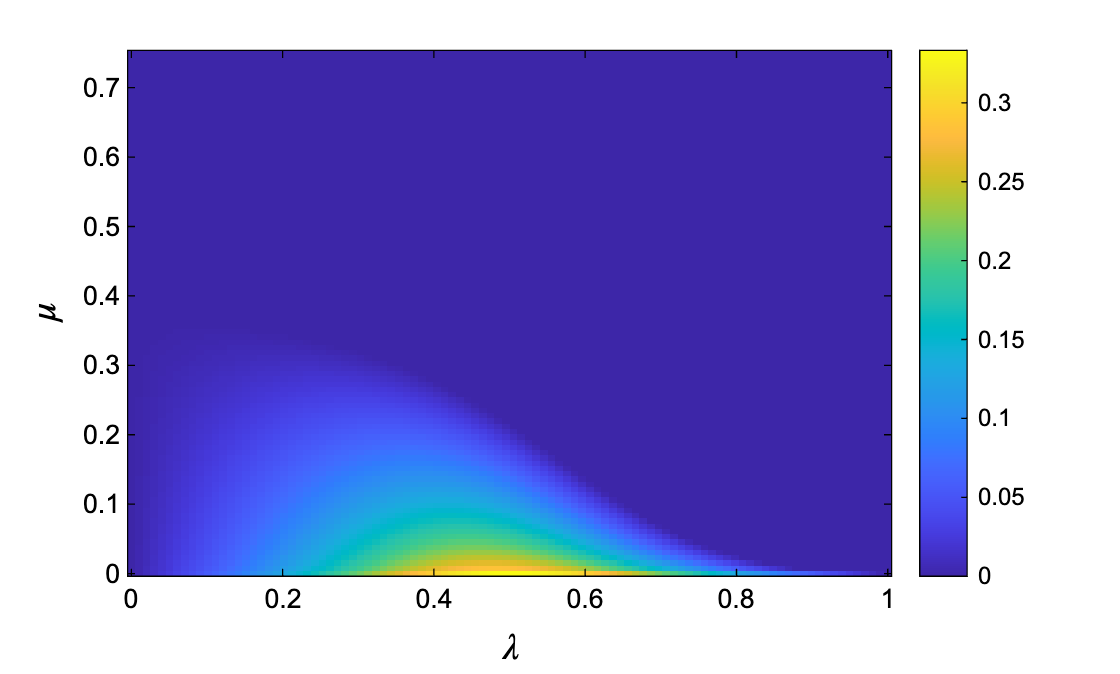


figure('Color', 'w');
imagesc(lambda_vec, mu_vec, Entanglement); 
set(gca, 'YDir', 'normal','FontName', 'Arial'); 

hold on; 


target_z = 0.85;
[C, h] = contour(lambda_vec, mu_vec, Entanglement, [target_z, target_z], ...
                 'LineColor', 'w', ...      
                 'LineWidth', 2, ...        
                 'LineStyle', '--');        


clabel(C, h, 'FontSize', 10, 'Color', 'w', 'Interpreter', 'latex');

hold off;

colorbar; 
colormap('parula'); 


set(gca, 'XColor', 'k', 'YColor', 'k');

xlabel('$\lambda$', 'Interpreter', 'latex', 'Color', 'k', 'FontSize', 14);
ylabel('$\mu$', 'Interpreter', 'latex', 'Color', 'k', 'FontSize', 14);

cb = colorbar;
cb.Color = 'k'; 

exportgraphics(gcf, './figures/BB84Attack_Concurrence_6States.jpg', 'Resolution', 300);